# TVP-FAVAR

Based on the paper "Changes in the effects of monetary policy on disaggregate price dynamics" by Haroon Mumtaz, Philip Liu, and Christiane Baumister

clear
addpath('functions');
addpath('data');


data_table = readtable('/data/data_favar.xlsx', "Sheet" ,"data"); % table of size = 776×3


% extract the "Dates" column and store it as "dates" table
dates = table2array(data_table(:, 'DATE')); 


% removes the "Date" column from "data_table"
data_change = removevars(data_table,{'DATE'});
data_ffr = table2array(data_change); % size = (776 x 2)
data0 = data_ffr(:,1:end-1); % remove the last variable on federal funds rate: size(data0) = 




names_tab = readtable('/data/data_favar.xlsx', "Sheet" ,"var_names"); % variable names
names = table2array(names_tab);

index_tab = readtable('/data/data_favar.xlsx', "Sheet" ,"indicator"); % size(index) = 40 x 1
index = table2array(index_tab);


dindex=index(:,1); %dindex=1 for series that are log differenced dindex=3 differencing without logs
index=index(:,2);  %index=1 for 'fast moving' series

reps=15; %replications
burn=5; %burn in 
horizon=40;
T0=100;  %training sample
CHECK=1;
maxdraws=100;
%first difference the data where appropriate
data00=diffx(data0,dindex);
%standardise the data
data=standardise(data00);
betamat=getbeta(data,data00);%scaling factors to convert IRFs into original data units


%load policy rate and standardize it
z=data_ffr(:, end); % size(z) = 425 x 1
z=z(2:end);
z=standardise(z);

% if you see the error: matrix must be positive definite with real diagonal elements, 
% it is likely because the numbers are complex
% convert complex to real by applying the function real()


KK=2;  %number of factors
L=2;  %number of lags in the VAR
N=KK+1; %number of Variables in var K factors plus the interest rate
NN=cols(data);% size of the panel
T=rows(data);
%step 1 of the algorithm set starting values and priors

%get an intial guess for the factor via principal components
pmat=real(extract(data,KK));

%set priors for TVP parameters 
Y=[pmat z];
X=[];
for j=1:L
X=[X lag0(Y,j) ];
end
X=[X ones(rows(X),1) ];
Y=Y(L+1:end,:);
X=X(L+1:end,:);

y0=Y(1:T0,:);
x0=X(1:T0,:);
b0=x0\y0;
e0=y0-x0*b0;
sigma0=(e0'*e0)/T0;
V0=kron(sigma0,inv(x0'*x0));


%priors for the variance of the transition equation
Q0=V0*T0*3.5e-04;  %prior for the variance of the transition equation error
P00b=V0;                    % variance of the intial state vector  variance of state variable p[t-1/t-1]
beta0b=vec(b0)';       % intial state vector   %state variable  b[t-1/t-1]
Q=Q0;
%priors and starting values for aij
C0=chol(sigma0);
C0=C0./repmat(diag(C0),1,N);
C0=inv(C0)';
PC0=10;
amatx=zeros(1,N*(N-1)/2);
j=1;
for i=1:N-1
    temp=C0(i+1,1:i);
amatx(1,j:j+cols(temp)-1)=temp;
D0{i}=eye(cols(temp))*(10^(-3));
j=j+cols(temp);
end
DD=D0;


%remove training sample
data=data(T0+L+1:end,:);
z=z(T0+L+1:end,:);
Y=Y(T0+1:end,:);
X=X(T0+1:end,:);
pmat=pmat(T0+L+1:end,:);
T=rows(data);








beta0=Y(1,:);  %state vector S[t-1/t-1]
for i=1:L-1
    beta0=[beta0 zeros(1,N)];
end
ns=cols(beta0);
P00=eye(ns);  %P[t-1/t-1]
rmatin=ones(NN,1); %arbitrary starting value for the variance of the idiosyncratic component
%prior for the factor loadings
fload0=zeros(KK+1,1);
vfload0=eye(KK+1);
vg=0.01;
tg=5;
%priors and starting values for the stochastic vol
hlast=(diff(Y).^2)+0.0001;
hlast=[hlast(1:2,:);hlast];  %rough intial guess for svol
g=ones(N,1);  %rough guess for the variance of the transition equation
g0=0.01^2;  %scale parameter for inverse gamma
Tg0=1;
mubar=log(diag(sigma0));
sigmabar=10;
%50 iterations to smooth initial estimates of stochastic volatility
epsilon=diff(Y);
epsilon=[epsilon(1,:);epsilon];
for m=1:50
  hnew=zeros(T+1,N);
  for i=1:N
      htemp=getsvol(hlast(:,i),g(i),mubar(i),sigmabar,epsilon(:,i));
      hnew(:,i)=htemp;
      
  end
hlast=hnew;
end

amat=repmat(amatx,T,1);
beta20=repmat(beta0b,T,1);


mm=1;
for m=1:reps;

%gibbs sampling 
 disp(strcat('REPS=',num2str(m)));

%step 1 sample factor loadings
[fload,floadr,rmat]=getobseqparameters(data,real(pmat),z,fload0,vfload0,vg,tg,rmatin,index);
rmatin=rmat;

%step 2 sample VAR coefficients

[beta2,error,roots,epsilon,problem]=carterkohnvar(Y,X,Q,amat,hlast,beta0b,P00b,L,CHECK,maxdraws);
if problem
    beta2=beta20;
else
    beta20=beta2;
end

% step 3 sample Q from the IW distribution
errorq=diff(beta2);
scaleQ=(errorq'*errorq)+Q0;
Q=iwpq(T+T0,invpd(real(scaleQ)));

%step4 sample aij using the carter kohn algorithm
QA=zeros((N*(N-1))/2,(N*(N-1))/2);
j=1;
for i=2:N
    ytemp=error(:,i);
    xtemp=error(:,1:i-1)*-1;
    a0=C0(i,1:i-1);
    pa=PC0*diag(abs(a0));
    Qa=DD{i-1};
    [a1,trash]=carterkohn1(a0,pa,hlast(:,i),Qa,ytemp,xtemp);
    amat(:,j:j+cols(a1)-1)=a1;
    %sample Qa
    a1errors=diff(a1);
    scaleD1=(a1errors'*a1errors)+D0{i-1};
    DD{i-1}=iwpq(T+T0,invpd(real(scaleD1))); %draw from inverse Wishart
    QA(j:j+cols(a1)-1,j:j+cols(a1)-1)=DD{i-1};
    j=j+cols(a1);
end
  

%Step 5 sample stochastic vol for each epsilon using the MH algorithm
  hnew=zeros(T+1,N);
  for i=1:N
      htemp=getsvol(hlast(:,i),g(i),mubar(i),sigmabar,epsilon(:,i));
      hnew(:,i)=htemp;
       gerrors=diff(log(hnew(:,i)));
g(i)=IG(Tg0,g0,gerrors);  %draw from the inverse Gamma distribution
  end
hlast=hnew;


%step 6 prepare matrices for the state space
%Y=H*factors+e
%factors=MU+F*Factors(-1)+v
%e~N(0,R)
%v~N(0,Q)

%matrix of factor loadings
H=zeros(NN,N*L);
H(1:rows(fload),1:KK+1)=[fload floadr];
H(rows(floadr)+1,KK+1)=1;
%matrix R
R=diag([rmat;0]);

pmat=getfactor(beta2,amat,hlast,H,R,data,z,beta0,P00,KK,ns,N,L);


%update data
Y=[pmat z];
Y=[Y(1:L,:);Y];
X=[];
for j=1:L
X=[X lag0(Y,j) ];
end
X=[X ones(rows(X),1) ];
Y=Y(L+1:end,:);
X=X(L+1:end,:);

if m>burn
    %compute impulse response
    for i=1:T
    iamat=invpd(chofac(N,amat(i,:)'));
    Sigma=iamat*diag(hlast(i+1,:))*iamat';    
    A0=cholx(Sigma);
    beta1=reshape(beta2(i,:),N*L+1,N);
    shock=zeros(1,N);
    shock(end)=1;
    yhat=irfsim(beta1,N,L,A0,shock,horizon);
    yhat=yhat./yhat(1,end);
yhat1=yhat*H(:,1:KK+1)';  %impulse response for the panel


irfmat(mm,i,1:horizon,1:NN+1)=(yhat1);
    end
mm=mm+1;
end
    

end

REPS=1
REPS=2
REPS=3
REPS=4
REPS=5
REPS=6
REPS=7
REPS=8
REPS=9
REPS=10
REPS=11
REPS=12
REPS=13
REPS=14
REPS=15


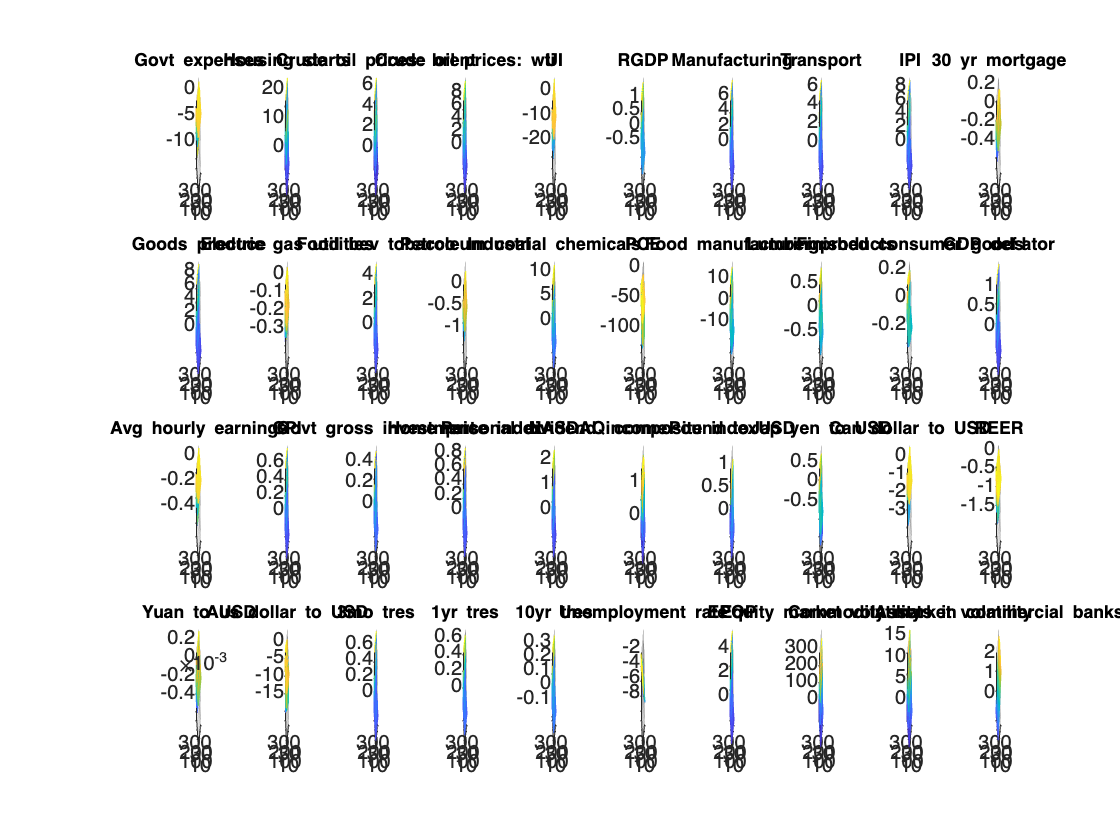







figure(1)
j=1;
for i=1:size(real(irfmat),4)-1
subplot(4,10,j)
set(gcf,'renderer','zbuffer')
irf=squeeze(prctile(real(irfmat(:,:,:,i)),[50],1));


mesh(cumsum(irf.*betamat(i),2));
title(strcat('\fontsize{8}', names(i)))
j=j+1;
axis tight
end